% Clear workspace
clear; clc;

% 1. Define variables and boundary conditions
a = 0; 
b = 1; 
alpha = 0; 
beta = 1;

% 2. Define functions for y'' + y = x
p = @(x) 0; 
q = @(x) 1; 
r = @(x) x; 

% Step sizes to test as requested
h_values = [0.2, 0.1, 0.05]; 
colors = {'g-o', 'r-s', 'm-^'}; % Green circles, Red squares, Magenta triangles

figure; hold on;
fprintf('   h    |  x      | Numerical y | Exact y  | Error\n');

   h    |  x      | Numerical y | Exact y  | Error


fprintf('--------------------------------------------------\n');

--------------------------------------------------



for k = 1:length(h_values)
    h_current = h_values(k);
    
    % n = (total length / h) - 1
    n = round((b - a) / h_current) - 1;

    % 3. Call the function
    [x, y] = solve_bvp_fd(p, q, r, a, b, alpha, beta, n);

    % 4. Exact solution (y = x)
    y_exact_vec = x;

    % 5. Compare at x = 0.5
    [~, idx] = min(abs(x - 0.5)); % Finds the closest point to 0.5
    
    fprintf('%6.2f  | %6.1f  | %10.6f  | %8.6f | %e\n', ...
            h_current, x(idx), y(idx), x(idx), abs(y(idx) - x(idx)));

    % 6. Plot numerical results
    plot(x, y, colors{k}, 'LineWidth', 1.5, 'MarkerSize', 8, 'DisplayName', ['h = ', num2str(h_current)]);
end

  0.20  |    0.4  |   0.400000  | 0.400000 | 1.110223e-16
  0.10  |    0.5  |   0.500000  | 0.500000 | 1.110223e-16
  0.05  |    0.5  |   0.500000  | 0.500000 | 1.554312e-15


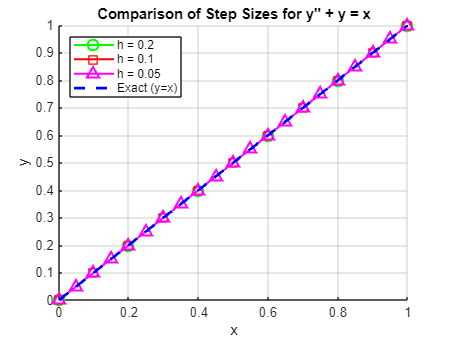


% Plot Exact Solution
fplot(@(x) x, [a, b], 'b--', 'LineWidth', 2, 'DisplayName', 'Exact (y=x)');

% Formatting
legend('Location', 'northwest');
xlabel('x'); ylabel('y');
title('Comparison of Step Sizes for y'''' + y = x');
grid on;


%% --- Function Definition ---
function [x, y] = solve_bvp_fd(p, q, r, a, b, alpha, beta, n)
    h = (b - a) / (n + 1);
    x = linspace(a, b, n + 2)'; 
    x_inner = x(2:end-1);

    A = zeros(n, n);
    B = zeros(n, 1);

    for i = 1:n
        xi = x_inner(i);
        A(i, i) = -2 + h^2 * q(xi);
        if i > 1, A(i, i-1) = 1 - (h/2) * p(xi); end
        if i < n, A(i, i+1) = 1 + (h/2) * p(xi); end
        B(i) = h^2 * r(xi);
    end

    % Boundary adjustments
    B(1) = B(1) - (1 - (h/2)*p(a+h))*alpha;
    B(end) = B(end) - (1 + (h/2)*p(b-h))*beta;

    y_inner = A\B;
    y = [alpha; y_inner; beta];
end